% This script demonstrates the control algorithm that is based on the
% optimization over reachable sets for the cart benchmark

% benchmark parameter
Param = param_cart(); 

% algorithm settings
Opts = [];

Opts.N = 10;                    % number of time steps
Opts.refTraj.Q = diag([5,5]);   % state weighting matrix (reference traj.)
Opts.refTraj.R = 1e-3;          % input weighthig matrix (reference traj.)

% controller synthesis
[objContr,res] = optimizationBasedControl('cart',Param,Opts);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.

                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0     21      28.0193       -0.999                                         
    1     43      25.3536      -0.4995          0.5        -1.96         4.79   
    2     65      18.5123      -0.2497          0.5        -2.45         10.1  Hessian modified  
    3     87      12.5949      -0.1249          0.5        -3.43         15.2  Hessian modified  
    4    109      8.01207     -0.06244          0.5        -4.15         14.9  Hessian modified  
    5    131      5.10566     -0.03122          0.5        -5.12         9.05  Hessian modified  
    6    153      3.58832     -0.01561          0.5        -6.04         7.01  Hessian modified  
    7    174      1.15333        0.287            1       -0.961      

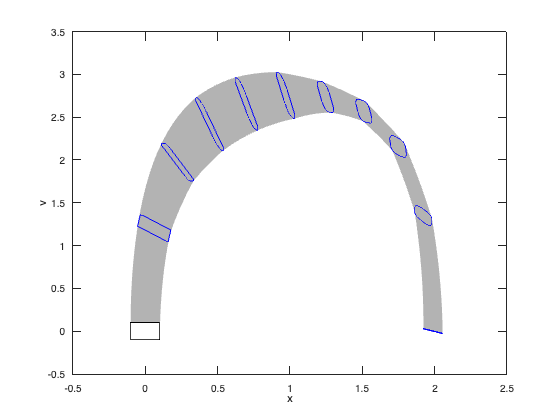


% visualization
figure; hold on; box on
plotReach(res,[1,2],[.7 .7 .7]);
plotReachTimePoint(res,[1,2],'b');
plot(Param.R0,[1,2],'FaceColor','w','EdgeColor','k');
xlabel('x'); ylabel('v');